# Breast Cancer Detection

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and formats the data.

bcDiag = readtable("./data/breastCancerData.csv");
bcDiag.diagnosis = categorical(bcDiag.diagnosis);

Partition the data into training and test sets.

pt = cvpartition(bcDiag.diagnosis, "HoldOut", 0.3);
bcTrain = bcDiag(training(pt), :);
bcTest = bcDiag(test(pt), :)

bcTest = 170×31 table
    diagnosis    radiusMean    radiusStandardError    radiusMax    textureMean    textureStandardError    textureMax    perimeterMean    perimeterStandardError    perimeterMax    areaMean    areaStandardError    areaMax    smoothnessMean    smoothnessStandardError    smoothnessMax    compactnessMean    compactnessStandardError    compactnessMax    concavityMean    concavityStandardError    concavityMax    concavePointsMean    concavePointsStandardError    concavePointsMax    symmetryMean    symmetryStandardError  

## Task 1

The table `bcDiag` contains measurements computed from digitized images of breast masses. The response variable is named `"diagnosis"` and contains the diagnosis of each mass as benign (`B`) or malignant (`M`).

Fit classifier and calculate loss.

mdl = fitcknn(bcTrain, "diagnosis", "NumNeighbors", 5);
errRate = loss(mdl, bcTest)

errRate = 0.0708

## Task 2

False negatives are masses where the true diagnosis is malignant, but the predicted diagnosis is benign. The false negative rate is different from the misclassification rate, which includes benign masses that are misclassified as malignant.

Calculate false negative rate.

p = predict(mdl, bcTest);
falseNeg = mean((bcTest.diagnosis == "M") & (p == "B"))

falseNeg = 0.0471

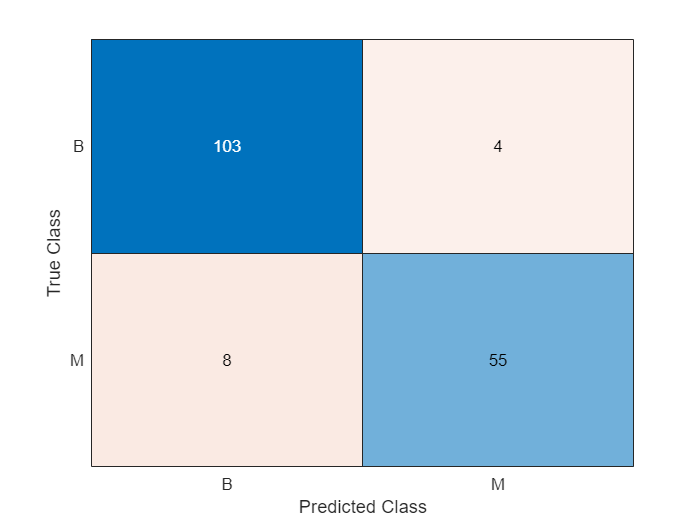

confusionchart(bcTest.diagnosis, p);